receive channel response from white noise input

% recObj = audiorecorder;
% disp('start receiving.');
% recordblocking(recObj, 5);
% disp('end receiving');
% h_received = getaudiodata(recObj);
% plot(h_received);

Estimate impulse response of channel

% h_xcorr = xcorr(h_received, n);
% plot(h_xcorr)
% for i=1:size(h_xcorr)
%     if h_xcorr(i) > 1
%         break
%     end
% end
% for j=size(h_xcorr):-1:1
%     if h_xcorr(j) > 1
%         break
%     end
% end
% h = h_xcorr(i:j);
% plot(h)

receive response from encoded text input

% recObj = audiorecorder(44100, 8, 1);
% disp('start receiving.');
% recordblocking(recObj, 8);
% disp('end receiving');
% y = getaudiodata(recObj);
% plot(y);

n: input white noise

h_received: received response from white noise input

h: estimated channel response

y: received response from encoded text message

load data_12_3_pm_2.mat

Text decoding with digital costas method

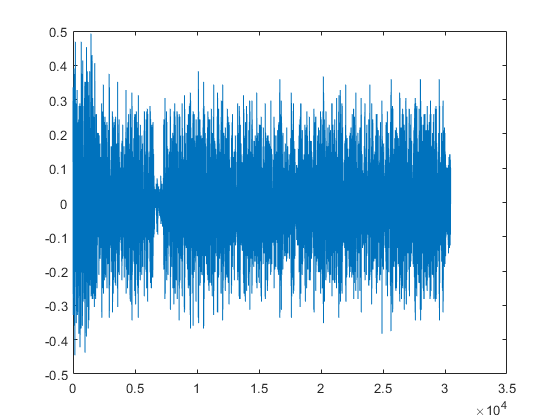

% locate received signal
% plot(y)
for i=1:size(y)
    if y(i) > 0.1
        break
    end
end
for k=size(y):-1:1
    if y(k) > 0.1
        break
    end
end
y_received = y(i:k);
plot(y_received)

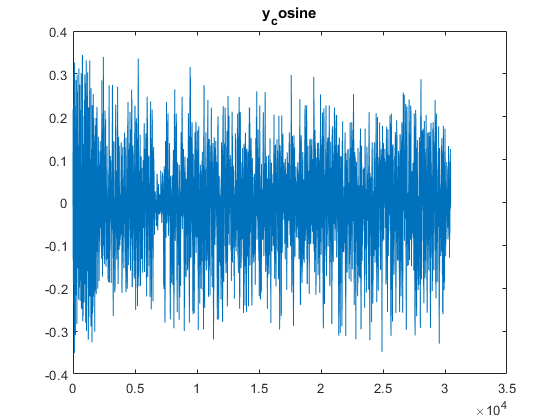


% cosine and sine
fc = 2000;
fs = 44100;
time = [0:length(y_received)-1]*1/fs;
y_cos = y_received.*cos(2*pi*fc*time.');
y_sin = - y_received.*sin(2*pi*fc*time.')*1i;
figure();
plot(y_cos)
title('y_cosine')

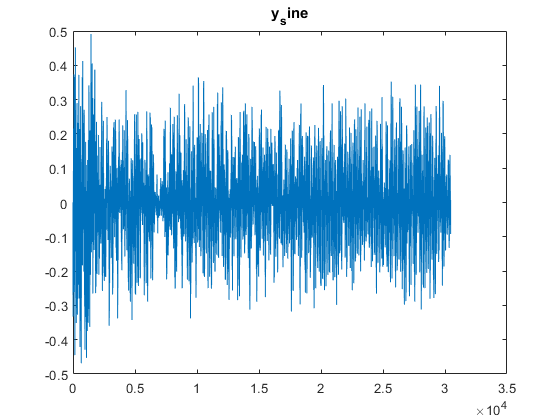

figure();
plot(imag(y_sin))
title('y_sine')

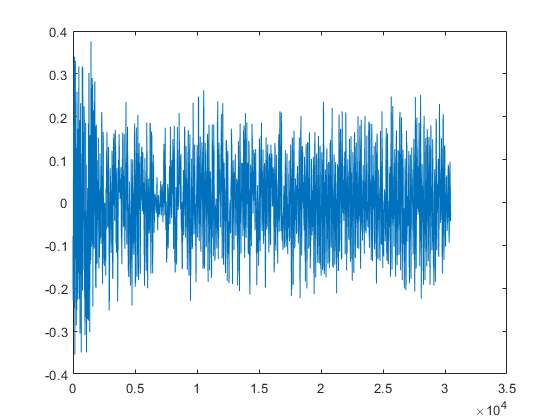

y_complex = y_cos + y_sin;
% we are not sure about the parameters for lowpass filter
y_complex = lowpass(y_complex, fc, 44.1e3);
plot(imag(y_complex))

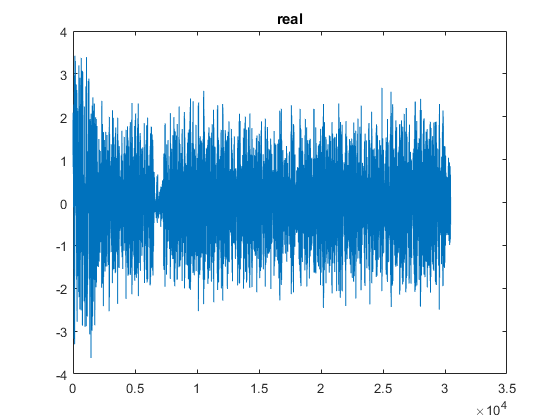


% normalize received signal
y_mag = rms(y_complex);
y_complex = y_complex ./ y_mag;
y_size = size(y_complex);

% initialize all variables
phi = zeros(y_size(1),1);
x_prime = zeros(y_size(1),1);
e = zeros(y_size(1), 1);
d = zeros(y_size(1),1);
k = 1;
%setting the value for alpha and beta
beta = 0.1;
alpha = 0.01;

% loop through k and minize error
while k < y_size(1)
    x_prime(k) = y_complex(k) * exp(j*phi(k));
    e(k) = -real(x_prime(k)) * imag(x_prime(k));
    d(k) = beta * e(k) + alpha * sum(e(1:k));
    phi(k+1) = phi(k) + d(k);
    while phi(k+1) < -pi
        phi(k+1) = phi(k+1) + 2*pi;
    end
    while phi(k+1) > pi
        phi(k+1) = phi(k+1) - 2*pi;
    end
    k = k + 1;
end
plot(real(x_prime))
title('real')

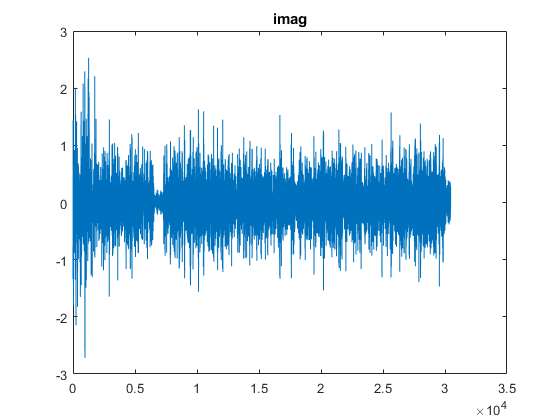

plot(imag(x_prime))
title('imag')

convert bit string to text

x_res = downsample(x_prime, 20);
% converting to 1 and 0
for i=1:size(x_res)
    if x_res(i) > 0
        x_res(i) = 1;
    end
    if x_res(i) < 0
        x_res(i) = 0;
    end
end

% break down long string into individual character
full_str = sprintf('%d',x_res');
% diff is added here to correct for possible offset
diff = 1;
full_str = full_str(1+diff:1491+diff);
str_size = idivide(int16(strlength(full_str)),int16(7));
ascii_list = strings(str_size, 1);
for i = 0:str_size-1
    ascii_list(i+1) = full_str(i*7+1:(i+1)*7);
end
result = "";
for i = 1:str_size
    result = append(result, char(bin2dec(ascii_list(i))));
end
result

result =     "t>ST((OT6R!ed3DsY@{Nf9L?\&9Mf!YN3L`[q`ilF~gsx dv9LgHKL6	L3Hlc	GaI~LGLs(Fc$b3g3r1\6DsDvF3t;03X6Lf3v@3N'63f1Lfy&9Lc8Ff{F3F3L3V56+vLc^kHOyN1f3
     C97y3 scFsFqf;"
